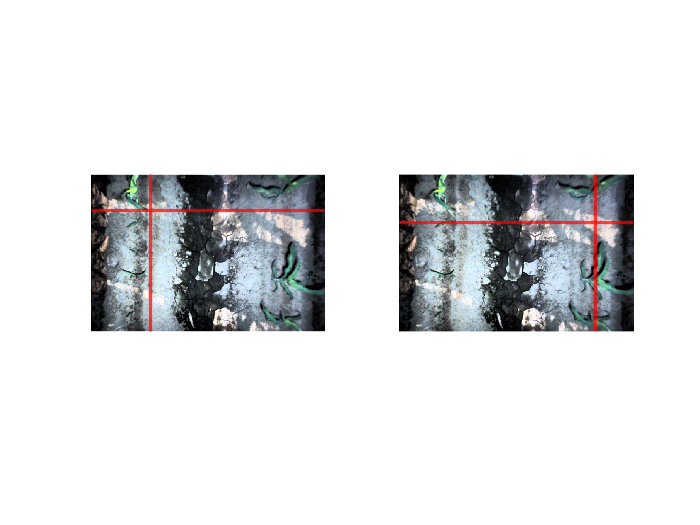

clear; close all; clc % clear workspace at the beginning 

dataPath = 'Images/'; % a string for the path to folder where image are placed

imagesList = dir([dataPath '*.png']); % Get a list of all PNG files in the path

imgNo = 1;    % Let0s process first image in the directory, as an example 

im_raw = imread([dataPath imagesList(imgNo).name]); % Load first file as MATLAB array

im_process = im2double(im_raw); % A rescaling function from Image Processing toolbox

% We can process other files in a similar way 

noImg = length(imagesList); % Number of files in folder

row = 683 ;
column = 1022 ;
binary_img = ones(row, column) ;

total_sum1 = 0 ;
number_of_line1 = 0 ;

total_sum2 = 0 ;
number_of_line2 = 0 ;

plant_number = 0 ;
plant1_sum = 0 ;
plant2_sum = 0 ;


for indx = 1:noImg       

    im_raw = imread([dataPath imagesList(indx).name]);

    % Task 1.1
    raw_HSV = rgb2hsv(im_raw);

    raw_HSV(:,:,3) = histeq(raw_HSV(:,:,3));
     
    raw_histed_RGB = hsv2rgb(raw_HSV);

    im_processed = im2double(raw_histed_RGB); 
    
    im_processed2 = flipud(im_processed); 

    % Subplots
    
    title(sprintf('Original Image %i',indx)); axis image


    title('Result'); axis image
    
    % Task 2.1
    R = im_processed2(:,:,1);
    G = im_processed2(:,:,2);
    B = im_processed2(:,:,3);
    
    NDI = (G-R)./(G+R) ;
    ExG = (2.*G) - R - B;
    ExR = (1.4*R) - G;
    ExB = (1.4*B) - G;
    ExGR = ExG - ExR - ExB ;
    
    % Task 2.2
    threshold = graythresh(ExGR) ;

    vegetation = im_processed2;

    vegetation_grayimage = rgb2gray(vegetation);

    vegetation_green = imsubtract(vegetation(:,:,2), vegetation_grayimage);

    vegetation_mask = im2bw(vegetation_green, 0.04) ;

    rgbImage = cat(3, vegetation_mask, vegetation_mask, vegetation_mask);

    final_image = im_processed2 .* rgbImage;


    title("Masked image") ;

    % Task 3.1
    m = sum(vegetation_mask) ;
  
    % Task 3.2 && 3.3  
    peaks = m ;

    peak_1 = peaks(1 : 500) ;

    max_peak_1 = max(peak_1) ;

    peak_2 = peaks(501 : 1022);

    max_peak_2 = max(peak_2) ;
    
    % Line 1
    vertical_line1 = find(m == max_peak_1) ;

     max_line1 = max(vertical_line1) ;

    total_sum1 = total_sum1 + max_line1 ;

    if(total_sum1)
        number_of_line1 = number_of_line1 + 1 ;
    end

    avg_line1 = total_sum1 / number_of_line1 ;

    all_horizontal_line_1 = max(avg_line1) ;
    
    % Line 2
    vertical_line2 = find(m == max_peak_2) ;

    max_line2 = max(vertical_line2) ;

    total_sum2 = total_sum2 + max_line2 ;

    if(total_sum1)
        number_of_line2 = number_of_line2 + 1 ;
    end

    avg_line2 = total_sum2 / number_of_line2 ;

    all_horizontal_line_2  = max(avg_line2) ;
       
    
    
    plant_line_1 = max(sum(vegetation_mask(:,1:511))') ;
    plant_line_2 = max(sum(vegetation_mask(:,512:1022))') ;

    plant1_sum = plant1_sum + plant_line_1 ;
    plant2_sum = plant2_sum + plant_line_2 ;

    subplot(1,2,1)
    imshow(im_processed2)
    xline([all_horizontal_line_1], 'r', 'linewidth', 2)
    yline([plant_line_1], 'r', 'LineWidth',2)

    if plant_line_1 > 243
        plant_number = plant_number + 1;
    end

    subplot(1,2,2)
    imshow(im_processed2)
    xline([all_horizontal_line_2], 'r', 'linewidth', 2)
    yline([plant_line_2], 'r', 'LineWidth',2)

    if plant_line_1 > 240 
        plant_number = plant_number + 1;
    end


    pause(0.1); % pause for 1 sec before showing next results
end

plant1avg = plant1_sum / 50 ;
plant2avg = plant2_sum / 50 ;
plant_number 

plant_number = 52